adata_obs=readtable('combine_adata_st_obs.csv');

rng(1);
Rcolor=rand(1000,3,'double');%[0.50073644, 0.98585307, 0.68441523; 0.07618405, 0.59789999, 0.27389582; 0.88541192, 0.91174287, 0.67716287; 0.49888577, 0.2692925 , 0.168824  ; 0.50254477, 0.81804417, 0.89023576; 0.22412601, 0.64535127, 0.89231617; 0.07367916, 0.79614377, 0.06814698; 0.11072297, 0.22896638, 0.50881243; 0.87621758, 0.66374928, 0.85861207; 0.13254612, 0.81012957, 0.46849738; 0.35931568, 0.46881892, 0.28105022; 0.78532594, 0.94309353, 0.74803515; 0.3838704 , 0.29606876, 0.89715318; 0.54601439, 0.37861424, 0.98458877; 0.76594675, 0.93241955, 0.18215191; 0.04290206, 0.30901371, 0.57713386; 0.27730869, 0.25665752, 0.547854  ; 0.6765545 , 0.22049784, 0.25719179; 0.53226053, 0.14554901, 0.07569058; 0.56905297, 0.04241662, 0.41548396; 0.94387832, 0.47618687, 0.88772186; 0.04457812, 0.67691415, 0.2396106 ; 0.10104427, 0.61935348, 0.75119081; 0.12501159, 0.15065496, 0.52871108; 0.7454498 , 0.2432429 , 0.75109417; 0.18617131, 0.68537728, 0.05271072; 0.20022221, 0.78253542, 0.41052029; 0.43128533, 0.34266265, 0.85824113; 0.64148718, 0.32461655, 0.81102081; 0.87785032, 0.2924339 , 0.27556315; 0.08707779, 0.26109255, 0.91194055; 0.69820949, 0.34686463, 0.74441555; 0.93271158, 0.45280799, 0.36666694; 0.91467761, 0.03304377, 0.40218128; 0.38473675, 0.56135467, 0.85068308; 0.49359172, 0.2697674 , 0.59780932; 0.19100293, 0.86178859, 0.56140191; 0.742361  , 0.01315983, 0.87002084; 0.851059  , 0.05113972, 0.67605016; 0.0473292 , 0.8025787 , 0.93314722];
% celltype=adata_obs.Rank5_subcluster;
% celltypeunique=unique(celltype);
% 
% [~,celltypeid_all]=ismember(celltype,celltypeunique);
% 
% %remove
% adata_obs=adata_obs(celltypeid_all>1,:);
% celltypeid_all=celltypeid_all(celltypeid_all>1);
% 
% celltype=adata_obs.Rank5_subcluster;
% celltypeunique=unique(celltype);
% 
% [~,celltypeid_all]=ismember(celltype,celltypeunique);

celltypeid_all=adata_obs.celltypeid_all;

wellname_all=unique(adata_obs.sample);
% {'sagittal1',
%     'sagittal2',
%     'sagittal3',
%     'well3_5',    
%     'well1_5',    
%     'well10_5',
%     'spinalcord',    
%     'well11',    
%     'well10',    
%     'well09',    
%     'well06',
%     'well07',    
%     'well08',    
%     'well01OB',    
%     'well01brain',    
%     'well7_5'};

unique_celltype={};
for i =0:230
    test=adata_obs.Rank5_Symbol(adata_obs.celltypeid_all==i);
    unique_celltype(i+1)=test(1);
end

id=0:230;
tissueid=id';
rank5_symbol=unique_celltype';
test=table(tissueid,rank5_symbol);
writetable(test,'tissueid_rank5_symbol.csv')

for i_batch=1:3
    batch=wellname_all{i_batch};
    test=ismember(adata_obs.sample,batch);
    celltypeid_well=celltypeid_all(test);
    celltypeid_well=celltypeid_well+1;
    M_all=[adata_obs.col(test),adata_obs.row(test),adata_obs.z(test)];
    
    
    M_gpu=gpuArray(M_all);
    NUMBER=size(M_gpu,1);
    SAMPLE=1000;
    [sizebyk_cpu,sizebyk_dis_cpu] = DPC_1(M_gpu,NUMBER,SAMPLE);
    
    
    cell_typecompos=zeros(size(M_all,1),231);
    for i=1:size(M_all,1)
        for j=1:SAMPLE
            if sizebyk_dis_cpu(i,j)<=500
                cell_typecompos(i,celltypeid_well(sizebyk_cpu(i,j)))=cell_typecompos(i,celltypeid_well(sizebyk_cpu(i,j)))+1;
            else
                break;
            end
        end
        if j==500
            p=0;
        end
    end
    writematrix(cell_typecompos,['output_data/cell_typecompos_',batch,'_500.csv']);
end

% cell_typecompos=readmatrix('cell_typecompos_well04.csv');

% adjacent_matrix=zeros(size(M_all,1),size(M_all,1));
% for i=1:size(M_all,1)
%     for j=1:SAMPLE
%         if sizebyk_dis_cpu(i,j)<=500
%             adjacent_matrix(i,sizebyk_cpu(i,j))=adjacent_matrix(i,sizebyk_cpu(i,j))+1;
%         end
%     end
% end

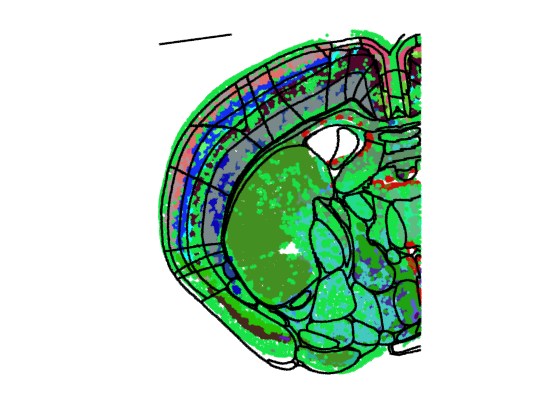

cell_typecompos_all=cell_typecompos;
% cell_typecompos_all(:,994:996)=0.0001*(M_all);

idx=kmeans(cell_typecompos_all,30);

Rcolor = rand(length(unique(idx)),3,'double');
figure;
for i=1:length(unique(idx))
    hold on
    test=find(idx==i);
    plot(max(M_all(:,2))-M_all(test,2),M_all(test,1),'.','Color',Rcolor(i,:),'MarkerSize',7);
end
axis equal
axis off

ccf_annotation=imread(['J:\ClusterMap2\ccf\AP_histology-master_sagittal\slices\annotation\ccf_','well04_celltypemap-rgb-1','.tif']);

% plot boundary
[Gmag, ~] = imgradient(ccf_annotation,'prewitt');
Gmag=uint8(Gmag);
point_at_boundary=find(Gmag>0);
sz=size(Gmag);
[row,col] = ind2sub(sz,point_at_boundary);
hold on;
plot(col*10,max(row*10)-row*10,'k.','markersize',3);